# Path planning

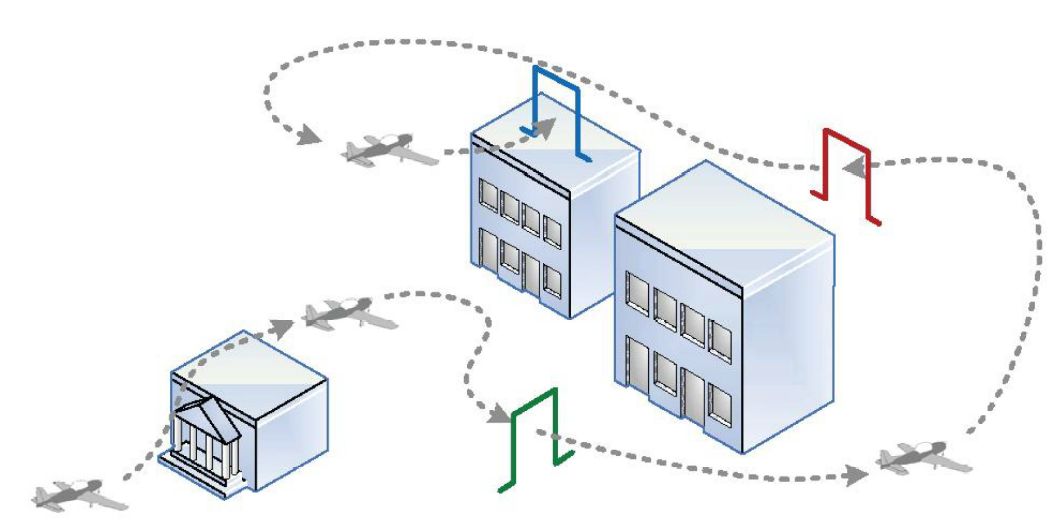

The objective of the polinomial based path planning is to obtain a function that satisfies  the boundary conditions, meaning it meets the requirements of position,  velocity, acceleration, etc. 

These conditions are known to the user.

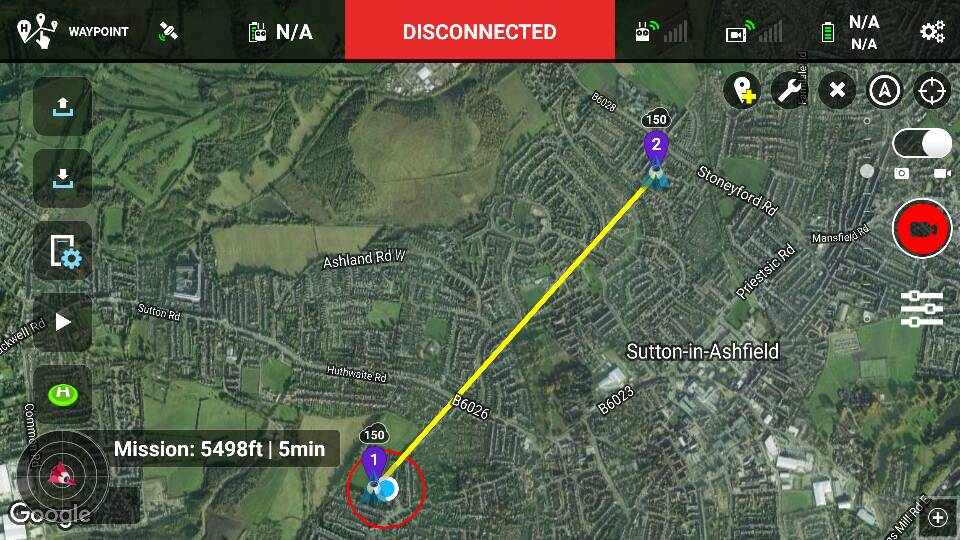

For instance

Point A:

UAV on ground

Position  (x,y,z,yaw)=(0,0,0,0)

Velocity (x,y,z,yaw)=(0,0,0,0)

Point B:

UAV on hover

Position (x,y,z,yaw)=(10,10,10,0)

Velocity (x,y,z,yaw)=(0,0,0,0)

The objective, then, is to obtain all the points that compound the yellow line in the figure above. The simplest way to solve this problem is to use polynomials of an appropriate degree.

The degree of the polynomial is directly dependent on the number of boundary conditions.

Let's assume that we want to obtain the trajectory of the previous image and that we only want to control position and velocity. Therefore, the boundary conditions for position in X are as follows:

Point A:

UAV on ground (X startl)

Position; xini=0;

Velocity vxini=0;

Point B:

UAV on hover (X finish)

Position; xf=10;

Velocity vxf=0;

Taking into account this data, we have 4 boundary conditions; therefore, to solve the problem, we need to generate at least a polynomial of degree 3.

Our problem, is obtaining the values of the coefficients.

To obtain them, it is necessary to generate a system of equations as follows:

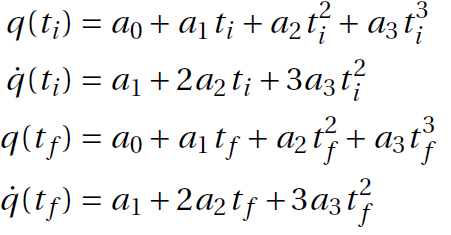

The first two equations are related to the initial position and velocity, while the last two depend on the final position and velocity. One equation is needed for each boundary condition.

Knowing that the initial time, $t_i=0$, and substituting it into the first two equations:

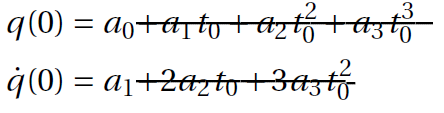

It is possible to obtain the coefficients a0 and a1 in a simple manner, as


$$\begin{array}{l}
\textrm{Initial}\;\textrm{Position}=q\left(0\right)=a_0 =0\\
\textrm{Initial}\;\textrm{Velocity}=\overset{\ldotp }{q} \left(0\right)=a_1 =0
\end{array}$$


To obtain the values of the remaining coefficients (a2 and a3), it is necessary to use the equations related to the final time. Therefore, based on the problem data,


$$\textrm{Final}\;\textrm{Position}=q\left(\textrm{tf}\right)=10=a_0 +a_1 \textrm{tf}+a_2 {\textrm{tf}}^2 +a_3 {\textrm{tf}}^3$$


Where:

a0=0

a1=0

Therefore,


$$q\left(\textrm{tf}\right)=0+0+a_2 {\textrm{tf}}^2 +a_3 {\textrm{tf}}^3 =10$$


Making the same substitutions in the final velocity equation, we obtain:


$$\overset{\ldotp }{q\left(\textrm{tf}\right)} =0+2a_2 \textrm{tf}+3a_3 {\textrm{tf}}^2 =0$$


Therefore, to obtain the missing coefficients, it is necessary to solve a system of two equations with two unknowns. To do this, it is necessary to rearrange the previous equations into conventional form.


$$\textrm{AX}=B$$


Where:

A = Square matrix formed by the values dependent on time (tf's)

X = Vector of coefficients to be found.

B = Known results and values in each of the equations.

For our particular case, the system of equations to be solved is:


$$\left\lbrack \begin{array}{cc}
{\textrm{tf}}^2  & \textrm{tf}\\
2\textrm{tf} & 3{\textrm{tf}}^2 
\end{array}\right\rbrack *\left\lbrack \begin{array}{c}
a_2 \\
a_3 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
10\\
0
\end{array}\right\rbrack$$


Therefore, the system can be solved as follows:$\mathrm{X}={\mathrm{A}}^{-1} B$

The MATLAB code would then be as follows:

tf=150% Number of points

tf = 150

A=[tf^2 tf^3; 2*tf 3*tf^2]

A =        22500     3375000
         300       67500


%% For "x"
xd=10 % Desired position for "X"

xd = 10

xpd=0% Desired Velocity for "X"

xpd = 0

a0=0  %Initial condition for X position

a0 = 0

a1=0  %Initial condition for X Velocity

a1 = 0

B=[10;0]

B =     10
     0


coef=(inv(A))*B

coef =     0.0013
   -0.0000


a2=coef(1)

a2 = 0.0013

a3=coef(2)

a3 = -5.9259e-06

rev=A*coef

rev =    10.0000
    0.0000


    Once we have obtained the coefficients of the polynomials, it is necessary to generate all the points in our path. To do this, we need to calculate the position and velocity values.

for n=1:1:tf
    %%  Points
    px(n)=a0+a1*n+a2*n^2+a3*n^3; %X position
    vx(n)=a1+2*a2*n+3*a3*n^2; %X Velocity
    t(n)=n;
    
end

Plot the paths

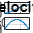

figure('Name','X','NumberTitle','off')
subplot(2,1,1)
plot(t,px)
axis([0 tf+3 0 xd+3]) 
xlabel('Time [s]','FontSize',10)
ylabel('')
title('Position','FontSize',10)
grid on
%%%%%%%%%%%%%%%%%%%%%%%%%%%%
subplot(2,1,2)
plot(t,vx)
axis([0 tf+3 0 0.12]) 
xlabel('Time [s]','FontSize',10)
ylabel('')
title('Velocity','FontSize',10)
grid on